# MATLAB Project: Signal Noise Analysis and Reduction

This project is designed to deepen your understanding of digital signal processing, specifically focusing on noise analysis and reduction in audio signals. Through this project, you will work with original and noisy audio files, with the objectives to analyze noise characteristics, create custom noisy signals, and apply various noise reduction techniques to reconstruct the original audio as accurately as possible. 

## Part 1: Noise Reduction in Provided Audio

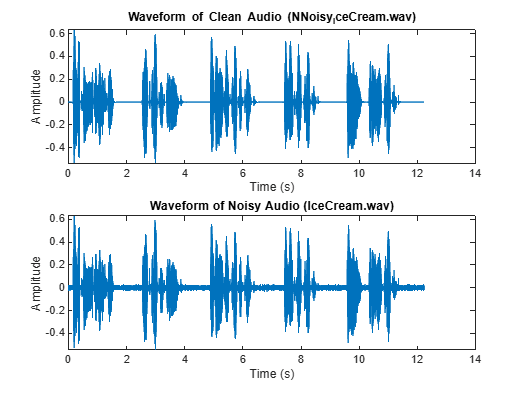


% Task 1: Preliminary Analysis - Load and visualize audio files
% Load original and noisy audio files
[noisy_audio, Fs1] = audioread('IceCream.wav');
[clean_audio, Fs2] = audioread('NNoisy_IceCream.wav'); % "NNoisy" stands for "Not Noisy"

sound(noisy_audio,Fs1); 
pause(length(noisy_audio)/Fs1);  % Wait for first sound to finish
sound(clean_audio,Fs2);          % plays second audio file
pause(length(clean_audio)/Fs1);  % Wait for first sound to finish

% Create time vectors for plotting
t1 = (0:length(noisy_audio)-1)/Fs1;
t2 = (0:length(clean_audio)-1)/Fs2;

% Visualize waveforms for initial comparison
figure(1);
subplot(2,1,1);
plot(t2, clean_audio);
xlabel('Time (s)'); ylabel('Amplitude');
title('Waveform of Clean Audio (NNoisy_IceCream.wav)');

subplot(2,1,2);
plot(t1, noisy_audio);
xlabel('Time (s)'); ylabel('Amplitude');
title('Waveform of Noisy Audio (IceCream.wav)');

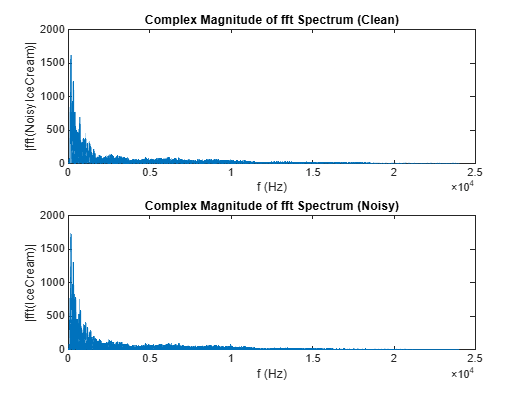

%Task 2: Frequency Domain Analysis
%Perform FFT to analyze frequency components of both signals

clean_fft = fft(clean_audio);
fft_noisy = fft(noisy_audio);
L_clean = length(clean_audio);
L_noisy = length(noisy_audio);

% Plot frequency spectrum
figure(2);
subplot(2,1,1);
plot(Fs2*(0:(L_clean/2))/L_clean, abs(clean_fft(1:floor(L_clean/2)+1)), 'LineWidth', 1.5);
 xlabel("f (Hz)"); ylabel("|fft(NoisyIceCream)|");
title("Complex Magnitude of fft Spectrum (Clean)");

subplot(2,1,2);
plot(Fs1*(0:(L_noisy/2))/L_noisy, abs(fft_noisy(1:floor(L_noisy/2)+1)), 'LineWidth', 1.5);
xlabel("f (Hz)"); ylabel("|fft(IceCream)|");
title("Complex Magnitude of fft Spectrum (Noisy)");

%Task 3: Noise Characterization
%Isolate and analyze noise components

% Identify the additional frequency components introduced by the noise.
noise = resize(noisy_audio, length(clean_audio)) - clean_audio;
N = length(noise);

% Analyze the mean and variance of the noise.
mean_noise = mean(noise);
variance_noise = var(noisy_audio);
fprintf('Noise mean: %e\n', mean_noise);

Noise mean: -2.335831e-05


fprintf('Noise variance: %f\n', variance_noise);

Noise variance: 0.005605


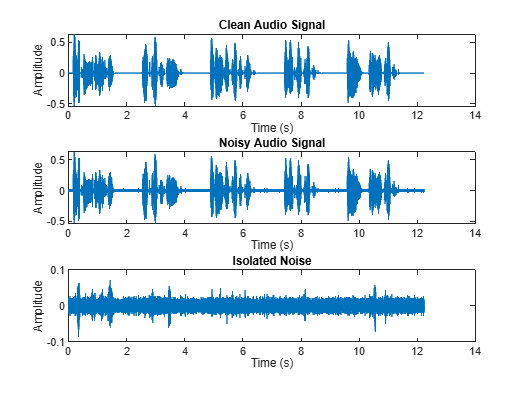


% Visualize original signals and isolated noise
figure(3);
subplot(3,1,1);
plot(t2, clean_audio);
xlabel('Time (s)'); ylabel('Amplitude');
title('Clean Audio Signal');

subplot(3,1,2);
plot(t1, noisy_audio);
xlabel('Time (s)'); ylabel('Amplitude');
title('Noisy Audio Signal');

subplot(3,1,3);
plot(t2, noise);
xlabel('Time (s)'); ylabel('Amplitude');
title('Isolated Noise');

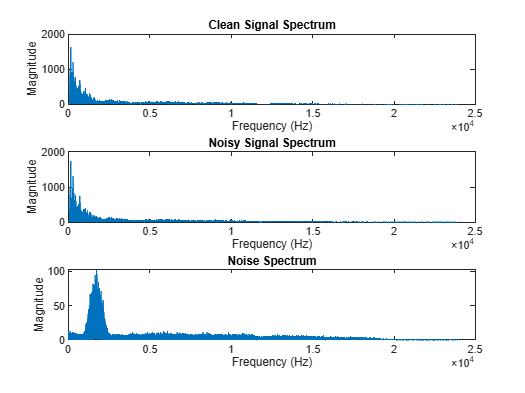


% Perform spectral analysis of the noise
noise_fft = fft(noise);
f_noise = Fs2*(0:(length(noise)/2))/length(noise);
f_clean = Fs2*(0:(L_clean/2))/L_clean;

figure(4);
subplot(3,1,1);
plot(f_clean, abs(clean_fft(1:floor(L_clean/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Clean Signal Spectrum'); 

subplot(3,1,2);
plot(f_noise, abs(fft_noisy(1:floor(length(noise)/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Noisy Signal Spectrum');

subplot(3,1,3);
plot(f_noise, abs(noise_fft(1:floor(length(noise)/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Noise Spectrum');


% Find dominant noise frequency
[max_noise_mag, max_idx] = max(abs(noise_fft(1:floor(length(noise)/2)+1)));
dominant_noise_freq = f_noise(max_idx);
fprintf('Dominant noise frequency: %.2f Hz\n', dominant_noise_freq); % 1730.34 Hz

Dominant noise frequency: 1730.34 Hz


% Task 4: Noise Reduction
% Design and apply a filter to remove the identified noise components from the noisy signal.

%Standardize input lengths for processing
noisy_audio_resized = resize(noisy_audio, length(clean_audio));

% Method 1: Notch filter for dominant frequency
% Analyze noise spectrum to determine bandwidth
noise_mag = abs(noise_fft(1:floor(length(noise)/2)+1));
threshold = max(noise_mag) / sqrt(2); % -3dB point
idx_range = find(noise_mag > threshold);
bandwidth = f_noise(idx_range(end)) - f_noise(idx_range(1));
fprintf('Estimated noise bandwidth: %.2f Hz\n', bandwidth);

Estimated noise bandwidth: 388.57 Hz



Q = dominant_noise_freq / bandwidth; % Quality factor
[b_notch, a_notch] = iirnotch(dominant_noise_freq/(Fs2/2), 1/Q);
y_notch = filtfilt(b_notch, a_notch, noisy_audio_resized);

% Method 2: Bandpass filter (if signal is in a specific range) % GROK SAYS RANGE IS TOO NARROW
low_freq = 100; high_freq = 8000; 
cutoff_freq = dominant_noise_freq; % Hz (estimate based on visual analysis)
filter_order = 6;
[b_band, a_band] = butter(filter_order, [low_freq high_freq]/(Fs2/2), 'bandpass');
y_bandpass = filtfilt(b_band, a_band, noisy_audio);

% Method 3: Spectral Subtraction
fft_noisy_resized = fft(noisy_audio_resized);
uniform_fft = fft(noise);
alpha = 1; % Over-subtraction factor
fft_clean_est = fft_noisy_resized - alpha * uniform_fft;
fft_clean_est = max(abs(fft_clean_est), 0) .* exp(1j * angle(fft_clean_est)); % Preserve phase
y_spectral = real(ifft(fft_clean_est));


% Normalize filtered signals to match original RMS
rms_clean = sqrt(mean(clean_audio.^2));
y_notch = y_notch * (rms_clean / sqrt(mean(y_notch.^2)));

y_bandpass = y_bandpass * (rms_clean / sqrt(mean(y_bandpass.^2)));
y_spectral = y_spectral * (rms_clean / sqrt(mean(y_spectral.^2)));

% Uncomment to listen to results
sound(y_notch, Fs2); pause(length(y_notch)/Fs2 + 1);
sound(y_bandpass, Fs2); pause(length(y_bandpass)/Fs2 + 1);
sound(y_spectral, Fs2); pause(length(y_spectral)/Fs2 + 1);

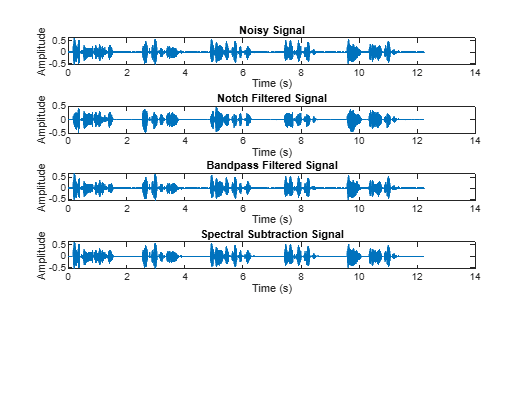

% Task 5: Reconstruction and Evaluation
% Plot filtered signals
figure(5);
subplot(5,1,1);
plot(t2, noisy_audio_resized);
title('Noisy Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,2);
plot(t2, y_notch);
title('Notch Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,3);
plot(t1, y_bandpass);
title('Bandpass Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,4);
plot(t2, y_spectral);
title('Spectral Subtraction Signal');
xlabel('Time (s)'); ylabel('Amplitude');


% Calculate SNR and MSE for each filtered signal
snr_notch = snr(clean_audio, clean_audio - y_notch);
snr_bandpass = snr(clean_audio, clean_audio - resize(y_bandpass,length(clean_audio)));
snr_spectral = snr(clean_audio, clean_audio - y_spectral);

mse_notch = mean((clean_audio - y_notch).^2);
mse_bandpass = mean((clean_audio - resize(y_bandpass, length(clean_audio))).^2);
mse_spectral = mean((clean_audio - y_spectral).^2);

output = sprintf(['Notch Filter: SNR = %.2f dB, MSE = %.6f\n' ...
                  'Bandpass Filter: SNR = %.2f dB, MSE = %.6f\n' ...
                  'Spectral Subtraction: SNR = %.2f dB, MSE = %.6f\n'], ...
                  snr_notch, mse_notch, ...
                  snr_bandpass, mse_bandpass, ...
                  snr_spectral, mse_spectral);

disp(output)

Notch Filter: SNR = 6.93 dB, MSE = 0.001121
Bandpass Filter: SNR = 13.58 dB, MSE = 0.000242
Spectral Subtraction: SNR = 300.09 dB, MSE = 0.000000




% Save the best filtered signal (based on best SNR/MSE)
audiowrite('Reconstructed_Audio.wav', y_notch, Fs2);

Part 2: Creation and Removal of Custom Noise

Generate and add uniform random noise within a specific frequency range to the original signal.

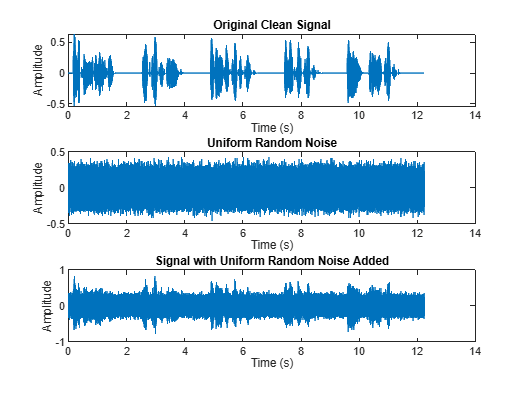

% Task 1: Create Custom Noisy Signals
% Uniform Random Noise Addition:

uniform_noise_component = 0.1 * randn(size(clean_audio));
uniform_noisy_signal = clean_audio + uniform_noise_component;

% Visualize and save this custom noisy signal
figure(6);
subplot(3,1,1);
plot(t2, clean_audio);
title('Original Clean Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,2);
plot(t2, uniform_noise_component);
title('Uniform Random Noise');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,3);
plot(t2, uniform_noisy_signal);
title('Signal with Uniform Random Noise Added');
xlabel('Time (s)'); ylabel('Amplitude');


% Save the noisy signal
audiowrite('Uniform_Noisy.wav', uniform_noisy_signal, Fs2);

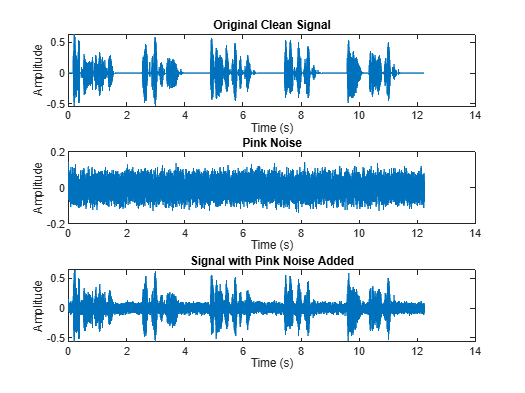

% 2. Pink Noise Addition
pink_noise_component = pinknoise(length(clean_audio));
pink_noisy_signal = clean_audio + pink_noise_component;

% Visualize pink noise addition
figure(7);
subplot(3,1,1);
plot(t2, clean_audio);
title('Original Clean Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,2);
plot(t2, pink_noise_component);
title('Pink Noise');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,3);
plot(t2, pink_noisy_signal);
title('Signal with Pink Noise Added');
xlabel('Time (s)'); ylabel('Amplitude');


% Save the pink noisy signal
audiowrite('Pink_Noisy.wav', pink_noisy_signal, Fs1);

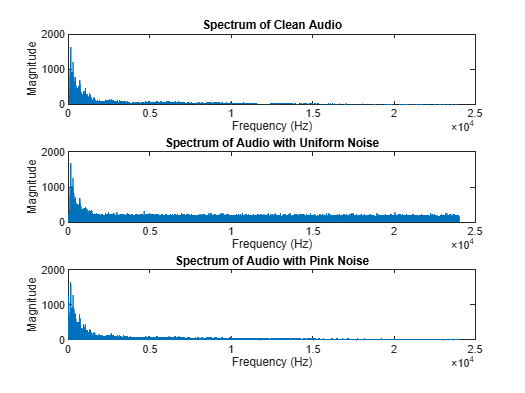

% Check frequency domain characteristics
uniform_fft = fft(uniform_noisy_signal);
pink_fft = fft(pink_noisy_signal);
clean_fft = fft(clean_audio);

figure(8);
subplot(3,1,1);
plot(f_clean, abs(clean_fft(1:floor(L_clean/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Spectrum of Clean Audio');


subplot(3,1,2);
plot(f_clean, abs(uniform_fft(1:floor(length(uniform_noisy_signal)/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Spectrum of Audio with Uniform Noise');


subplot(3,1,3);
plot(f_clean, abs(pink_fft(1:floor(length(pink_noisy_signal)/2)+1)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Spectrum of Audio with Pink Noise');

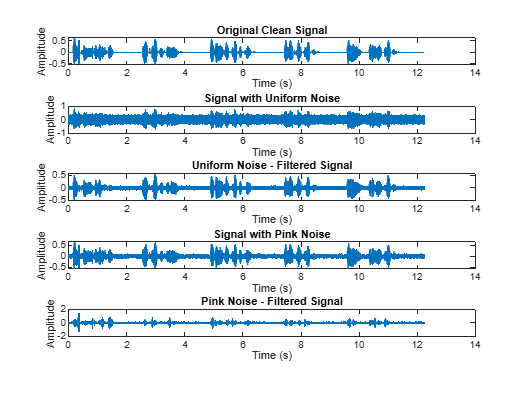

% Task 2: Noise Reduction and Signal Reconstruction
% Apply noise reduction techniques to both custom noisy signals.

% Uniform noise
H_wiener = abs(clean_fft).^2 ./ (abs(clean_fft).^2 + abs(uniform_fft).^2);
fft_filtered = uniform_fft .* H_wiener;
uniform_filtered = real(ifft(fft_filtered));
uniform_filtered = uniform_filtered * (rms_clean / sqrt(mean(uniform_filtered.^2)));


% Pink noise
% passband_freq_2 = 4000; % Hz
% stopband_freq_2 = 5000; % Hz
% [n_lowpass_2, Wn_lowpass_2] = buttord(passband_freq_2/(Fs1/2), stopband_freq_2/(Fs1/2), 3, 60);
% [b_low_2, a_low_2] = butter(n_lowpass_2, Wn_lowpass_2, 'low');
% pink_filtered = filtfilt(b_low_2, a_low_2, pink_noisy_signal);
% pink_filtered = pink_filtered * (rms_clean / sqrt(mean(pink_filtered.^2)));

cutoff_freq_pink = 1730; %200; 
[b_highpass, a_highpass] = butter(4, cutoff_freq_pink/(Fs1/2), 'high');
pink_filtered = filtfilt(b_highpass, a_highpass, pink_noisy_signal);% Plot the results
pink_filtered = pink_filtered * (rms_clean / sqrt(mean(pink_filtered.^2)));

% Plot results for custom noise reduction
figure(9);
subplot(5,1,1);
plot(t2, clean_audio);
title('Original Clean Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,2);
plot(t2, uniform_noisy_signal);
title('Signal with Uniform Noise');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,3);
plot(t2, uniform_filtered);
title('Uniform Noise - Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,4);
plot(t2, pink_noisy_signal);
title('Signal with Pink Noise');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(5,1,5);
plot(t2, pink_filtered);
title('Pink Noise - Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude');

sound(pink_filtered, Fs2); pause(length(pink_filtered)/Fs2 + 1);
sound(uniform_filtered, Fs2); pause(length(uniform_filtered)/Fs2 + 1);

Error using sound (line 79)
Timeout occurred while trying to communicate to the device.



% Calculate and display SNR improvement
clean_resized = resize(clean_audio, length(uniform_noisy_signal));
snr_uniform_before = snr(clean_resized, uniform_noisy_signal);
snr_uniform_after = snr(clean_resized, clean_resized - uniform_filtered);
snr_pink_before = snr(clean_resized, pink_noisy_signal);
snr_pink_after = snr(clean_resized, clean_resized - pink_filtered);



output = sprintf(['Uniform Noise: SNR Before = %.2f dB, SNR After = %.2f dB\n' ...
		  'Pink Noise: SNR Before = %.2f dB, SNR After = %.2f dB\n'], ...
		   snr_uniform_before, snr_uniform_after, ...
		   snr_pink_before, snr_pink_after);

disp(output)